clear all
close all

% 2) figuring out which constraint is being violated and trying to relax just that one. 
% Then going to hybrid using fmincon with fixed integer variables. That is relaxing the 
% problem constraint. Run ga. Take the answer and use the integer variables as fixed at 
% those values. Add back in the constraint and run fmincon on the continuous variables.  

%Define initial values of variables
x_initial = [50, 20, 10, 32, 100, 205, 12, 300, 120, 250, 56, 73, 15, 30, 10, 8, 50000000, 0.5, 20, 80, 44]

x_initial = 1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0000    0.0000    0.0000    0.0000    0.0000



% Define Drag Coefficient Regression:
global cd_mdl
%Variables: [angle_alpha, angle_beta, angle_gamma, num_cars]
%Solutiuon: [Coefficient of Drag]
var = [15,30,10,3;15,15,10,3;50,30,20,3;15,50,20,3;15,15,10,7;30,50,10,15;15,15,20,7;15,30,10,15;50,50,10,3;30,15,20,3;50,30,20,7;15,15,20,3]; 
sol = [0.7306;0.49511;0.603478;0.865479;0.825286;1.33042;0.7927;1.16979;0.869678;0.51569;1.02362;0.438809];
cd_mdl=fitlm(var,sol);

%test costObj function
[totalCost] = costObj(x_initial)

totalCost = single
943208704


%Run GA with relaxed earthquake constraints
%%% Set lower and upper bounds
%lower and upper bounds for train optimization
lb_network = [1,1,1,1,1,1,1,1,1,1,1,1];
ub_network = [133,307,133,307,133,307,133,307,133,307,133,307];

%lower and upper bounds for train optimization
lb_train =[15,15,10,3];
ub_train =[50,50,20,15];

%lower and upper bounds for safety optimization
lb_safety = [0 0 0 0 25];
ub_safety = [5000000000 1 60 200 100];

%Set overall lower and upper bounds
lb_total = [lb_network, lb_train, lb_safety] 

lb_total =      1     1     1     1     1     1     1     1     1     1     1     1    15    15    10     3     0     0     0     0    25


ub_total = [ub_network, ub_train, ub_safety]

ub_total = 1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0000    0.0000    0.0000    0.0000    0.0000



Single objective optimization:
21 Variables
13 Integer variables
32 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240         0.06535          0.4557        0
    2              360        0.007707          0.2526        0
    3              480        0.007707          0.1868        1
    4              600        0.007707          0.1214        2
    5              720        0.005751           0.124        0
    6              840        0.005333         0.06922        0
    7              960        0.002203         0.04937        0
    8             1080        0.002203         0.03248        1
    9             1200        0.001054         0.06316        0
   10         

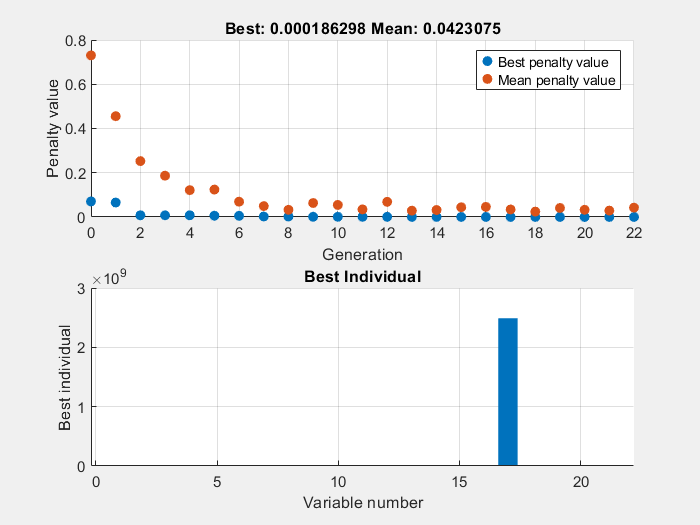


%%% Set GA parameters
lb = lb_total;
ub = ub_total;
intcon = [1,2,3,4,5,6,7,8,9,10,11,12,16]; 
nvars = 21;
nonlincon = @combinedNonlincon2;
fun = @costObj;


%intcon for network and safety 
intcon_network = [1, 2, 3, 4,5, 6, 7,8,9,10,11,12,16];
intocon_train = [4];

%options copied from Quinn's code:
options = optimoptions('ga', ...
    'Display', 'iter', ...                          
    'PlotFcn', {@gaplotbestf, @gaplotbestindiv}, ... 
    'UseParallel', false, ...                        % switched to false
    'PopulationSize', 120, ...
    'EliteCount', ceil(0.15 * 120), ...             % 15% of population kept as elite
    'CrossoverFraction', 0.70, ...                   % 70% of population undergoes crossover
    'CrossoverFcn', @crossoverlaplace, ...          % good for real-valued obj funcs
    'MutationFcn', @mutationadaptfeasible, ...      % adaptive mutation but only in the feasible space
    'SelectionFcn', @selectiontournament, ...       % tournament selection
    'MaxGenerations', 120, ...
    'FunctionTolerance', 1e-3, ...                  % stop if improvement in func value is very small
    'ConstraintTolerance', 1e-6, ...                % tight, but not zero, tolerance on constraints -->changed from 1e-3 to 0
    'InitialPenalty', 5, ...
    'PenaltyFactor', 100, ...                       % quickly increase penalties for violating constraints
    'MaxStallGenerations', 20);                     % stop if no improvement (beyond tolerance) after 20 generations

%Run GA
[x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);

%add x_star from ga as parameter in fmincon?
%Run fmincon
lb = [lb_safety];
ub = [lb_safety];
x0 = [50000000, 0.5, 20, 80, 44];
[x_star2,fval,exitflag,output] = fmincon(@costObj2,x0,[],[],[],[],lb,ub,@combinedNonlincon3)


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



x_star2 =      0     0     0     0    25


fval = 650627968

exitflag = -2

output = struct with fields:
         iterations: 1
          funcCount: 7
    constrviolation: 3.9432e+03
           stepsize: 0
          algorithm: 'interior-point'
      firstorderopt: 0
       cgiterations: 0
            message: 'Converged to an infeasible point.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance but constraints are not↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, but the relative maximum constraint↵violation, 1.000000e+00, exceeds options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: []


%calculate individual scores
convenience_score = networkScore(x_star(1:12))

convenience_score = single
-0.3861

train_veloc = TrainVelocity(predict(cd_mdl,x_star(13:16)))

train_veloc = 63.1181

number_of_accidents = accident_count_function(x_star(16:21))

number_of_accidents = 1.8061

fval_individual = [convenience_score, train_veloc, number_of_accidents];

%calculate individual costs
network_cost = networkCost(x_star(1:12))

network_cost = single
578744512

train_cost = TrainCost(x_star(16))

train_cost = 157500000

safety_cost = safety_system_cost_function(x_star(17:21))

safety_cost = 4.7979e+08

costs_individual = [network_cost, train_cost, safety_cost]

costs_individual = 1×3 single row vector
   578744512   157500000   479793312
